# MATH 3620 Numerical Analysis

# Homework 1

# 29 Jan 2021

clear

## `Q1. Computing Machine Precision`

The code below computes machine precision. All variables are stored in double precision, which is default in MATLAB. 

format long
a = 4/3;
b = a - 1;
c = b + b + b;
eps0 = abs(c-1)

eps0 =      2.220446049250313e-16


The above code gives us a value of 

`eps0 = 2.220446049250313e-16`

Analytically, 

`eps0 = 0`

The difference arises because of the fact that the variable 

`a = 4/3`

is not represented exactly in memory. The division results in a roundoff error equal to 

`eps = 2^(-52) `

The second step in the code 

`b = a - 1`

maintains the round-off error from previous step since `1` is represented exactly in memory. 

The last bit of `b `equals `0, `and hence the third step in the code, which is computing `c, `can be completed with no round-off error. Hence, the quantity `eps0 `equals the machine precision, i.e. `eps0 = eps = 2^(-52) = 2.220446049250313e-16`

## `Q2. Computing y = x - sin(x)` 

format long
x = 0.01

x =    0.010000000000000


sinx = sin(x)

sinx =    0.009999833334167


y = x - sinx

y =      1.666658333357440e-07


Subtracting by hand results in `y = 1.666658330000000e-07.` 

The exact answer for *y* is `1.666658333353175e-07. `

Hence, **we lose atleast 4 digits**. Doing the same excercise **in binary with double precision, we lose 16 bits**.   

**Alternative Way to compute *****y***

An alternative way to compute *y *is to use the Taylor Series expansion of sin(*x*), which is

sin(*x*) = *x - x*^(3)/3! + *x*^(5)/5! - *x*^(7)/7! + *x*^(9)/9! - ...

Then *y = x - *sin(*x*) is

*y = x*^(3)/3! - *x*^(5)/5! + *x*^(7)/7! - *x*^(9)/9! + ...

**Verification**

y = 0;
for i = 1:4
    p = 2*i + 1;
    y = y + ((-1)^(i-1))*(x^p)/factorial(p);
end
y

y =      1.666658333353175e-07


As we can see, *y *is much more accurate with our alternate way of computation. 

## `Q3. Plotting y = x^2`

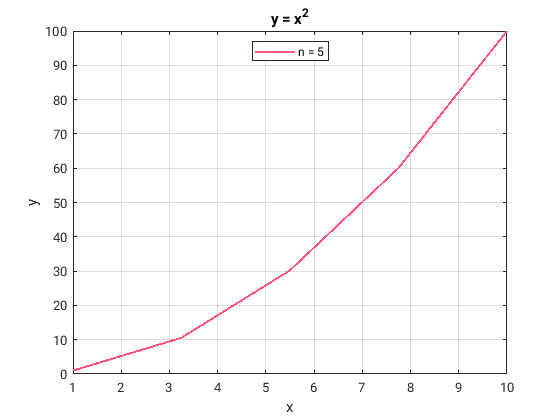

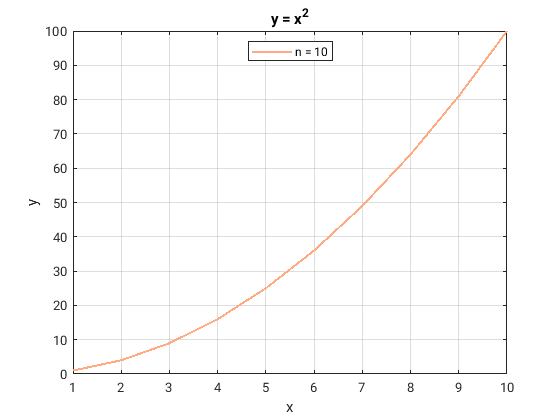

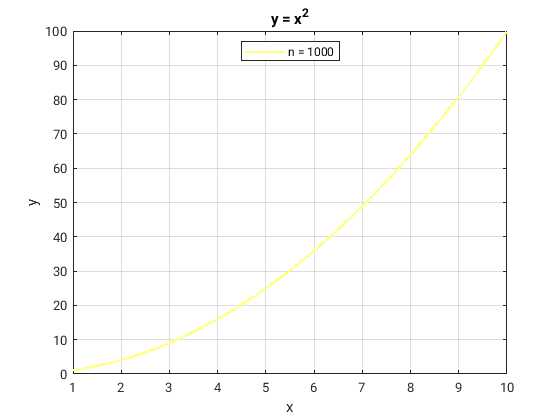

close all
format short
n = [5 10 1000];
for i = 1:length(n)
    delta = (10 - 1)/(n(i)-1);
    x = 1:delta:10;
    y = x.^2;
    figure()
    plot(x, y, "LineWidth", 1.5, "Color",[1 i/3 0.5])
    legendstr = ['n = ', num2str(n(i))];
    legend(legendstr, "Location","north")
    xlabel('x')
    ylabel('y')
    title('y = x^2')
    grid on
end

**Comments on Resolution:** The quality of plot clearly improves as we increase the number of data points *n*. However, the difference in quality of the plots obtained for *n* = 10 and *n* = 1000 does not seem proportional to the increase in number of data points, i.e. *n*. The plot with 10 data points is a "good enough" qualitative representation of the function.